close all;
clear;
clc;

## Data 1: x1, x2, u1, u2

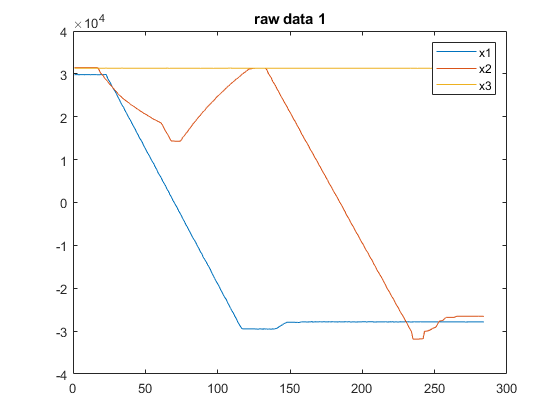

dataRaw1 = readtable("dataRecorded/waterTankRaw1.csv");

plot(dataRaw1.x1);
hold on;
plot(dataRaw1.x2);
plot(dataRaw1.x3);
legend("x1","x2","x3")
title("raw data 1")
hold off;

A=0.0154; %m^2
g = 9.81;

%calculate some stuff

% y = m * x + b
% b = y - m * x
%m = (y2-y1)/ (x1-x2)


### x1

x1 = dataRaw1.x1;

x1Empty = mean(x1(1:20));
x1Full = mean(x1(174:282));

m1 = (0.60) / (x1Full - x1Empty);
b1 = - m1 * x1Empty;

x1Out = x1.* m1 + b1;
plot(x1Out);
legend("x1")
title("raw data 1 x1 corrected")

x1Std = std(x1Out(1:20));


### x2

x2 = dataRaw1.x2;

x2Empty = mean([x2(125:132);x2(1:14)]);
x2Full = mean(x2(267:282));

m2 = (0.60) / (x2Full - x2Empty);
b2 = - m2 * x2Empty;

x2Out = x2.* m2 + b2;
plot(x2Out);
legend("x2")
title("raw data 1 x2 corrected")

x2Std = std([x2Out(125:132);x2Out(1:14)]);

### u1

t = (1:1:(115-36));
%t_delta = t(1)-Zeit(200);
h_delta = x1Out(115) - x1Out(37);

%Qz1 = x1Out(37:115)*A\t.'
Qz1 = h_delta*A/(115-37); %m^3/s


### u2

h_delta = x2Out(227) - x2Out(145);

%Qz1 = x1Out(37:115)*A\t.'
Qz2 = h_delta*A/(227 - 145); %m^3/s

## Data 2: x3, x32

dataRaw2 = readtable("dataRecorded/waterTankRaw2.csv");

% plot(dataRaw2.x1);
% hold on;
% plot(dataRaw2.x2);
% plot(dataRaw2.x3);
% legend("x1","x2","x3")
% title("raw data 2")
% hold off;

### x3

x3 = dataRaw2.x3;

x2 = dataRaw2.x2;
x2Out = x2.* m2 + b2;
x1 = dataRaw2.x1;
x1Out = x1.* m1 + b1;

x3Empty = mean(x3(237:591));
x3Full = mean(x3(1:14));

m3 = (0.60) / (x3Full - x3Empty);
b3 = - m3 * x3Empty;

x3Out = x3.* m3 + b3;
plot(x1Out);
hold on;
plot(x2Out);
plot(x3Out);
legend("x1","x2","x3")
title("raw data 2 x3 corrected")
hold off;

x3Std = std(x3Out(237:591))


### c32

start = 21;
stop = 118;
for n = 2:(stop-start)
    dx3(n) = (x3Out(start+n+1)-x3Out(start+n-1))/2;
    dx2(n) = (x2Out(start+n+1)-x2Out(start+n-1))/2;
    c32(n) = (dx3(n) * A) /( - sqrt(2 * g * (x3Out(start+n) - x2Out(start+n))));
    
    %c13(n) = (dh3(n)*A)/(sqrt(2*g*(x3Out(n)-x3Out(n))));
    
    %c13 = (dx3 * A) / sqrt(2 * g * (x1 - x3))
    
    %c32 = (dx2 * A) /  sqrt(2 * g * (x3 - x2))
end
plot(c32);
hold off;
c32mean = mean(c32(2:90))

## Data 3: c13, c2R

dataRaw3 = readtable("dataRecorded/waterTankRaw3.csv");
x1 = dataRaw3.x1;
x1Out = x1.* m1 + b1;
x2 = dataRaw3.x2;
x2Out = x2.* m2 + b2;
x3 = dataRaw3.x3;
x3Out = x3.* m3 + b3;

plot(x1Out);
hold on;
plot(x2Out);
plot(x3Out);
legend("x1","x2","x3")
title("data 3")
hold off;

### c13

start = 18;
stop = 122;
for n = 2:(stop-start)
    dx3(n) = (x3Out(start+n+1)-x3Out(start+n-1))/2;
    c13(n) = (dx3(n) * A) /( sqrt(2 * g * (x1Out(start+n) - x3Out(start+n))));
    
    %c13(n) = (dh3(n)*A)/(sqrt(2*g*(x3Out(n)-x3Out(n))));
    
    %c13 = (dx3 * A) / sqrt(2 * g * (x1 - x3))
    
    %c32 = (dx2 * A) /  sqrt(2 * g * (x3 - x2))
end
plot(c13);
c13mean = mean(c13(2:70))

### c2R

start = 33;
stop = 140;
for n = 2:(stop-start)
    dx2(n) = (x2Out(start+n+1)-x2Out(start+n-1))/2;
    c2R(n) = (dx2(n) * A) /( - sqrt(2 * g * (x2Out(start+n))));
end
plot(c2R);
c2Rmean = mean(c2R(2:70))

## c1R, c3R

dataRec4 = readtable("dataRecorded/waterTankLeckage1.csv");

x1 = dataRec4.x1;
x2 = dataRec4.x2;
x3 = dataRec4.x3;
plot(x1);
hold on;
plot(x2);
plot(x3);
legend("x1","x2","x3")
title("data 4")
hold off;

### c1R

start = 19;
stop = 134;
for n = 2:(stop-start)
    dx1(n) = (x1(start+n+1)-x1(start+n-1))/2;
    c1R(n) = (dx1(n) * A) /( - sqrt(2 * g * (x1(start+n))));
end
plot(c1R);
c1Rmean = mean(c1R(2:70))

### c3R

start = 15;
stop = 125;
for n = 2:(stop-start)
    dx3(n) = (x3(start+n+1)-x3(start+n-1))/2;
    c3R(n) = (dx3(n) * A) /( - sqrt(2 * g * (x3(start+n))));
end
plot(c3R);
c3Rmean = mean(c3R(2:70))

## Save parameter to file

parameter.c13 = round(c13mean,8);
parameter.c32 = round(c32mean,8);
parameter.c1R = round(c1Rmean,8);
parameter.c2R = round(c2Rmean,8);
parameter.c3R = round(c3Rmean,8);
parameter.u1 = round(Qz1,8);
parameter.u2 = round(Qz2,8);
parameter.A = 0.0154;
parameter.g = 9.81;


jsonParameter = jsonencode(parameter);
fid = fopen('dataOut/threeTankParameter2.json', 'w');
fprintf(fid, '%s', jsonParameter);
fclose(fid);
save("dataOut/threeTankParameter2","parameter");

## conversion for valve position measurement

dataRec5 = readtable("dataRecorded/waterTankValves2.csv");

v3 = dataRec5.v3;
v4 = dataRec5.v4;
v5 = dataRec5.v5;
plot(v3);
hold on;
plot(v4);
plot(v5);
legend("v3","v4","v5");
hold off;

### V3

v3Opened = mean([v3(1:120);v3(550:1300)]);
v3Closed = mean(v3(225:405));

mV3 = 1 / (v3Opened - v3Closed);
bV3 = - mV3 * v3Closed;

v3Out = v3.* mV3 + bV3;
plot(v3Out);
legend("v3")

### V4

v4Opened = mean([v4(1:550);v4(900:1300)]);
v4Closed = mean(v4(668:782));

mV4 = 1 / (v4Opened - v4Closed);
bV4 = - mV4 * v4Closed;

v4Out = v4.* mV4 + bV4;
plot(v4Out);
legend("v4")

### V5

v5Opened = mean(v5(1:1000));
v5Closed = mean(v5(1118:1132));

mV5 = 1 / (v5Opened - v5Closed);
bV5 = - mV5 * v5Closed;

v5Out = v5.* mV5 + bV5;
plot(v5Out);
legend("v5")

x3 = dataRaw1.x3.* m3 + b3;
std3 = std(x3(10:250));

x2 = dataRaw2.x2.* m2 + b2;
std2 = std(x2(300:500));

x1 = dataRaw2.x1.* m1 + b1;
std1 = std(x1(100:500));

stdV3 = std([v3Out(1:120);v3Out(550:1300)]);
stdV4 = std([v4Out(1:550);v4Out(900:1300)]);
stdV5 = std(v5Out(1:1000));

conversion.b1 = round(b1,6);
conversion.b2 = round(b2,6);
conversion.b3 = round(b3,6);
conversion.m1 = round(m1,8);
conversion.m2 = round(m2,8);
conversion.m3 = round(m3,8);
conversion.bV3 = round(bV3,5);
conversion.bV4 = round(bV4,5);
conversion.bV5 = round(bV5,5);
conversion.mV3 = round(mV3,8);
conversion.mV4 = round(mV4,8);
conversion.mV5 = round(mV5,8);
conversion.std1 = round(std1,6);
conversion.std2 = round(std2,6);
conversion.std3 = round(std3,6);
conversion.stdV3 = round(stdV3,6);
conversion.stdV4 = round(stdV4,6);
conversion.stdV5 = round(stdV5,6);

jsonConversion = jsonencode(conversion);
fid = fopen('dataOut/threeTankConversion3.json', 'w');
fprintf(fid, '%s', jsonConversion);
fclose(fid);
save("dataOut/threeTankConversion3","conversion");

## Test Data

dataSim = readtable("dataRecorded/waterTankTestDataRaw.csv");

y1Out =  dataSim.y1.* m1 + b1;
y2Out = dataSim.y2.* m2 + b2;
y3Out = dataSim.y3.* m3 + b3;



y1 = y1Out(6:196);
y2 = y2Out(6:196);
y3 = y3Out(6:196);

dx1 = zeros(length(y1),1);
dx2 = zeros(length(y1),1);
dx3 = zeros(length(y1),1);

for i = 1 : (length(y1) - 1)
   dx1(i,1) = y1(i+1,1) - y1(i,1);
   dx2(i,1) = y2(i+1,1) - y2(i,1);
   dx3(i,1) = y3(i+1,1) - y3(i,1);
end

y1 = y1(5:184);
y2 = y2(5:184);
y3 = y3(5:184);

dx1 = smoothdata(dx1(5:184));
dx2 = smoothdata(dx2(5:184));
dx3 = smoothdata(dx3(5:184));

x1 = y1;
x2 = y2;
x3 = y3;
time = (0 : 1 : (length(y1) - 1)).'; 

plot(y1)
hold on;
plot(y2)
plot(y3)
legend("y1","y2","y3")
title("test Data")
hold off;

plot(dx1)
hold on;
plot(dx2)
plot(dx3)
legend("dx1","dx2","dx3")
title("test Data del")
hold off;

testData = table(time,x1,x2,x3,dx1,dx2,dx3,y1,y2,y3);
save("dataOut/testData3.mat","testData");

writetable(testData,"dataOut/testData3.csv",'Delimiter',';');

load dataOut\testData5.mat

testData = [testData(1:54,:);testData(138:200,:)];
save("dataOut/testData6.mat","testData");
writetable(testData,"dataOut/testData6.csv",'Delimiter',';');